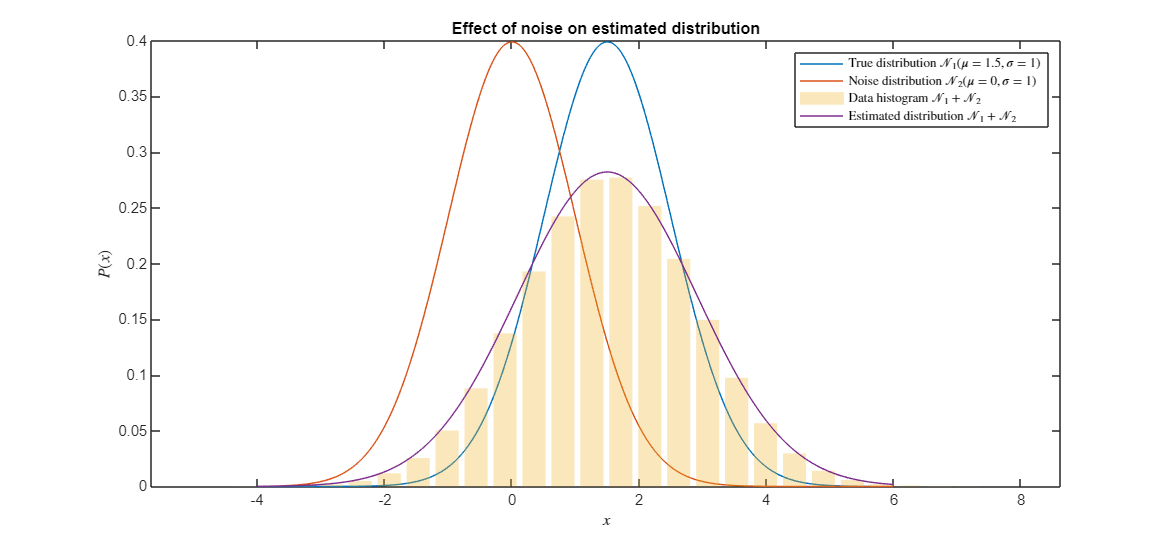

d = 30;
m = 1e6;

mu = 1.5;
sigma = 1;
noiseVar = 1;

normal = makedist('Normal', 'mu', mu, 'sigma', sigma);
noise = makedist('Normal', 'mu', 0, 'sigma', noiseVar);

t = -4:0.01:6;
range = t(end) - t(1);
bin_edges = linspace(t(1), t(end), d+1);
bin_centers = (bin_edges(1:end-1) + bin_edges(2:end)) / 2;

figure('Renderer', 'painters', 'Position', [10 10 1500 700])

% subplot(1, 2, 1);
y = pdf(normal, t); 
% plot(t, y); hold on;
% bar(bin_centers, pdf(normal, bin_centers) ,'FaceAlpha', 0.3, 'EdgeColor', 'none');

data = random(normal, m, 1) + random(noise, m, 1);
pd = fitdist(data, "Normal");
pdhist = histcounts(data, d, 'Normalization', 'probability');

data_bin_edges = linspace(min(data), max(data), d+1);
data_bincenters = (data_bin_edges(1:end-1) + data_bin_edges(2:end)) / 2;

plot(t, y); hold on;
plot(t, pdf(noise, t)); hold on;
bar(data_bincenters, (d/(sqrt(2)*range)) * pdhist ,'FaceAlpha', 0.3, 'EdgeColor', 'none'); hold on;
plot(t, pdf(pd, t));
ylabel("$P(x)$", 'Interpreter','latex')
xlabel("$x$", 'Interpreter','latex')
title("Effect of noise on estimated distribution")
legend(["True distribution $\mathcal{N}_1( \mu = $" + num2str(mu) + "$, \sigma =$" + num2str(sigma) + "$)$"], ...
    ["Noise distribution $\mathcal{N}_2( \mu = 0, \sigma =$" + num2str(noiseVar) + "$)$"], ...
    'Data histogram $\mathcal{N}_1 + \mathcal{N}_2$', ...
    'Estimated distribution $\mathcal{N}_1 + \mathcal{N}_2$', ...
    'Interpreter','latex')

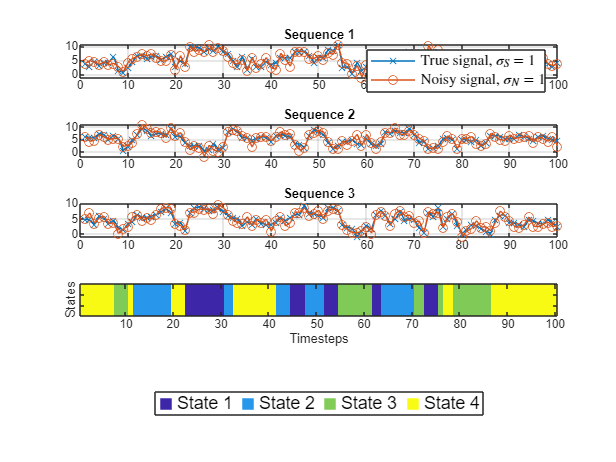


k = 4;
d = 50;
n = 3;
m = 1e2;

hmm_options.method = "random";
hmm_options.epsilon = 1/10;
hmm_options.distribution = 'Normal';


cmap = turbo(k);

[T, O, pi, ~, ~] = generateContinuousHMM(k, d, n, hmm_options);


observations = zeros(n, m);
states = zeros(1, m);

cumsum_pi = cumsum(pi);
cumsum_T = cumsum(T, 1);

% Sample initial state from pi
state = find(rand < cumsum_pi, 1);

for t = 1:m
    states(t) = state;

    % Sample observation from O(state, :)
    for i = 1:n
        observations(i, t) = random(O{i, state});
    end
    
    % Transition to the next state
    state = find(rand < cumsum_T(:, state), 1);
end




figure();

% --- Plot observation subplots ---
for i = 1:n
    subplot(n+2, 1, i);  % Reserve one extra row for the legend
    p1 = plot(1:m, observations(i, :), '-x'); hold on;
    p2 = plot(1:m, observations(i, :) + normrnd(0, noiseVar, 1, m), '-o');
    title(['Sequence '  num2str(i)]);
    grid on;
    
    % Add legend only on the first subplot
    if i == 1
        legend([p1, p2], {['True signal, $\sigma_S = $' num2str(sigma)], ['Noisy signal, $\sigma_N = $' num2str(noiseVar)]}, ...
       'Location', 'northeast', 'Interpreter','latex', 'FontSize', 10);
    end
end

% --- Plot HMM state subplot ---
cmap = parula(k);
colormap(cmap);

subplot(n+2, 1, n+1);  % Now the second-last row
imagesc(1:m, [0 1], states);
clim([1 k]);
ylabel("States");
set(gca,'YTickLabel',[]);
xlabel("Timesteps");
hold on;

% --- Add legend as an invisible axes at the bottom ---
legend_ax = subplot(n+2, 1, n+2);  % Last subplot row
axis off;  % Hide this subplot

% Create dummy handles for legend colors
hold on;
legendHandles = gobjects(k,1);
for i = 1:k
    legendHandles(i) = plot(nan, nan, 's', ...
        'MarkerFaceColor', cmap(i,:), ...
        'MarkerEdgeColor', cmap(i,:), ...
        'MarkerSize', 10);
end

legend(legendHandles, arrayfun(@(x) sprintf('State %d', x), 1:k, 'UniformOutput', false), ...
       'Orientation', 'horizontal', ...
       'Location', 'southoutside', ...
       'FontSize', 12);

% lgd.Layout.Tile = 'south';  % Places legend below all tiles